# 1.主轴跟踪(主轴环)

clear
clc
 
ulogOBJ = ulogreader("log_0_2021-6-30-08-04-24.ulg");
msg = readTopicMsgs(ulogOBJ);

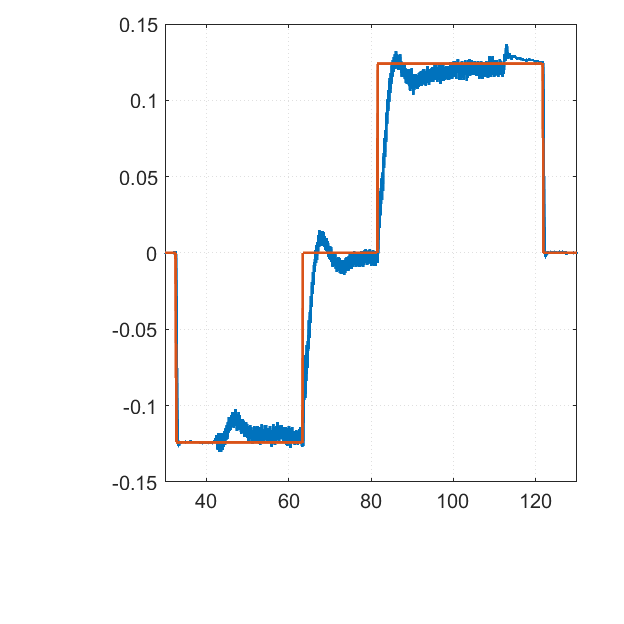

% 获取 known_logger 数据
logSampleRate = 50;
known_logger = msg.TopicMessages{12};
% 生成相对时间
log_time = known_logger.timestamp;
[sample_count,~] = size(log_time);
relativeTime = 0:1/logSampleRate:((sample_count-1)*(1/logSampleRate));
%
% 获取数据
h1 = known_logger.h1;
h2 = known_logger.h2;
h1d = known_logger.h1d;
h2d = known_logger.h2d;

% 画图
figure(11)
clf
plot(relativeTime, h1)
hold on 
plot(relativeTime,h1d)
xlim([30,130])

# 2.角速率跟踪(主轴环前飞后飞)

clear
clc
 
ulogOBJ = ulogreader("log_1_2021-6-30-08-04-50.ulg");
msg = readTopicMsgs(ulogOBJ);

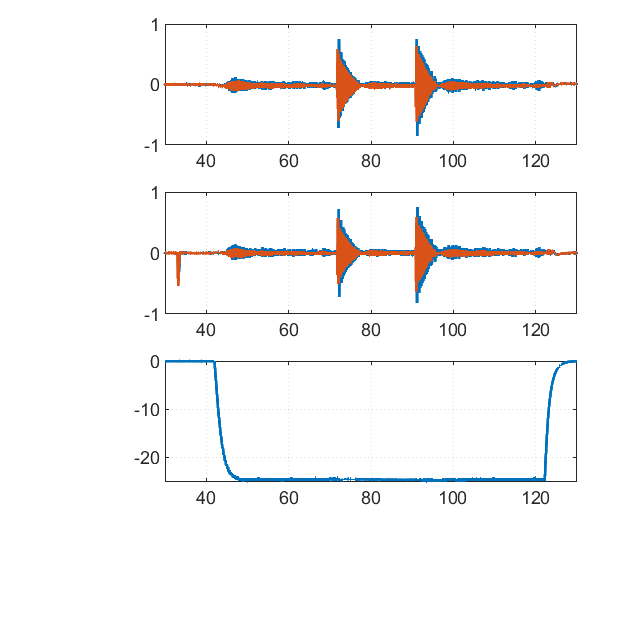

% 获取 known_logger 数据
logSampleRate = 50;
known_logger = msg.TopicMessages{12};
% 生成相对时间
log_time = known_logger.timestamp;
[sample_count,~] = size(log_time);
relativeTime = 0:1/logSampleRate:((sample_count-1)*(1/logSampleRate));

% 获取数据
pq = known_logger.pq;
pqd = known_logger.pqd;
r = known_logger.r;

% 画图
figure(21)
clf
subplot(3,1,1)
plot(relativeTime, pq(:,1))
hold on
plot(relativeTime, pqd(:,1))
xlim([30,130])

subplot(3,1,2)
plot(relativeTime, pq(:,2))
hold on
plot(relativeTime, pqd(:,2))
xlim([30,130])

subplot(3,1,3)
plot(relativeTime, r)
xlim([30,130])

# 3.虚拟通道对比(主轴环悬停)

clear
clc
 
ulogOBJ = ulogreader("log_7_2021-6-30-08-02-38.ulg");
msg = readTopicMsgs(ulogOBJ);

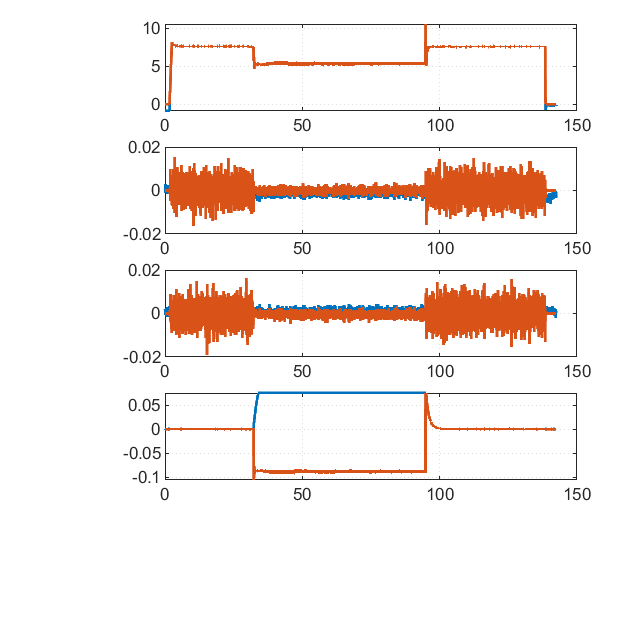

% 获取 known_logger 数据
logSampleRate = 50;
known_logger = msg.TopicMessages{12};
% 生成相对时间
log_time = known_logger.timestamp;
[sample_count,~] = size(log_time);
relativeTime = 0:1/logSampleRate:((sample_count-1)*(1/logSampleRate));

% 获取数据
chVDes = known_logger.chvdes;
tDes = known_logger.tdes;
loe = known_logger.loe;

% 选取和HIL中模型一致的控制分配矩阵参数
c = (0.0166);
l = (0.125);
% l = (0.225);
J = (diag([0.0056 0.0056 0.0104]));
% J = (diag([0.0194 0.0194 0.0291]));
M = ([ 1          1          1         1;
      -0.7071*l  -0.7071*l   0.7071*l  0.7071*l;
       0.7071*l  -0.7071*l  -0.7071*l  0.7071*l;
       c         -c          c        -c]);

% % 获取虚拟控制通道向量,即总的拉力和三个轴的力矩
% vAct = zeros(sample_count,4);
% for i = 1:sample_count
%     vAct(i,:) = M*((tDes(i,:))');
% end
% 获取实际的包含故障信息的虚拟控制通道向量
vActFault = zeros(sample_count,4);
for i = 1:sample_count
    vActFault(i,:) = M*((tDes(i,:))'.*[loe(i),1,1,1]');
end

% 画图
figure(31)
clf
subplot(4,1,1)
plot(relativeTime, chVDes(:,1))
hold on
plot(relativeTime, vActFault(:,1))

subplot(4,1,2)
plot(relativeTime, chVDes(:,2))
hold on
plot(relativeTime, vActFault(:,2))

subplot(4,1,3)
plot(relativeTime, chVDes(:,3))
hold on
plot(relativeTime, vActFault(:,3))

subplot(4,1,4)
plot(relativeTime, chVDes(:,4))
hold on
plot(relativeTime, vActFault(:,4))

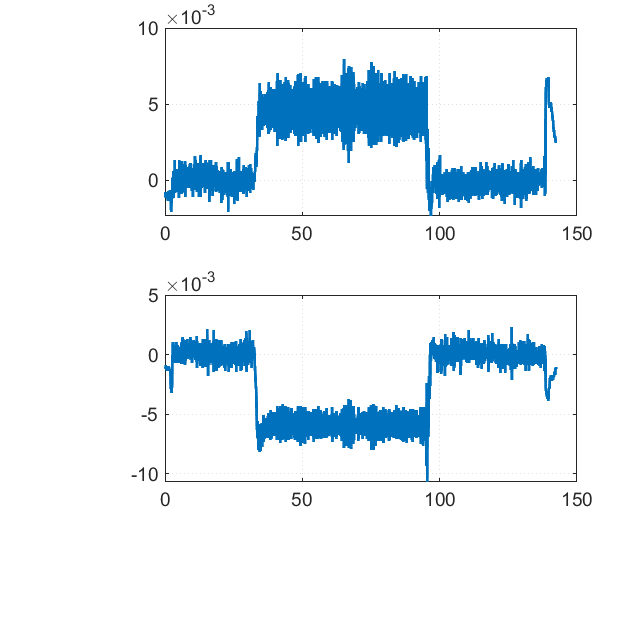

% 获取 vehicle_attitude 数据
logSampleRate = 20;
vehicle_attitude = msg.TopicMessages{35};
% 生成相对时间
log_time = vehicle_attitude.timestamp;
[sample_count,~] = size(log_time);
relativeTime = 0:1/logSampleRate:((sample_count-1)*(1/logSampleRate));

% 获取数据
quate = vehicle_attitude.q;

% 处理数据
[yaw, pitch, roll] = quat2angle(quate);

figure(32)
clf
subplot(2,1,1)
plot(relativeTime, roll)
subplot(2,1,2)
plot(relativeTime, pitch)